# **Test Lemniscata di Gerono **

**Simulazione della lemniscata di gerono, orientato attorno all'asse x o y, usando urdf e no**

## **Parametri della lemniscata**

flag = input('Scegli su quale asse orientare, 0 per asse x e 1 per asse y: ');
if flag == 0
    theta_y = 0;
    theta_x = input('Inserire angolo di rotazione attorno asse x, theta_x in radianti: ');
    [a, h, d_x, d_y] = lemniscate_parameters_x(theta_x);
elseif flag == 1
    theta_x = 0;
    theta_y = input('Inserire angolo di rotazione attorno asse y, theta_y in radianti: ');
    [a, h, d_x, d_y] = lemniscate_parameters_y(theta_y);
end

## **Robot**

q_traj_robot = lemniscata_gerono_robot(a,h,d_x,d_y,theta_x,theta_y);

## **Urdf**

q_traj =    -0.7299   -0.6458   -0.6644   -0.7755   -0.9574   -1.1618   -1.3202   -1.3921   -1.3799   -1.3098   -1.2166   -1.1326   -1.0796   -1.0680   -1.0991   -1.1581   -1.1868   -1.1165   -0.9224   -0.7299
    0.3166    0.2784    0.2332    0.1891    0.1325    0.0489   -0.0460   -0.1176   -0.1497   -0.1492   -0.1306   -0.1015   -0.0605   -0.0062    0.0562    0.1191    0.1865    0.2707    0.3254    0.3166
    2.6245    2.6083    2.5513    2.5264    2.5259    2.5205    2.4894    2.4366    2.3773    2.3214    2.2781    2.2633    2.2948    2.3766    2.4928    2.6088    2.6289    2.6392    2.6372    2.6245
   -0.0008   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0012   -0.0015   -0.0013   -0.0008
   -0.8356   -0.8119   -0.8235   -0.8043   -0.7482   -0.6700   -0.6063   -0.5874   -0.6146   -0.6710   -0.7329   -0.7768   -0.7864   -0.7588   -0.7049   -0.6520   -0.7020   -0.7769   -0.8

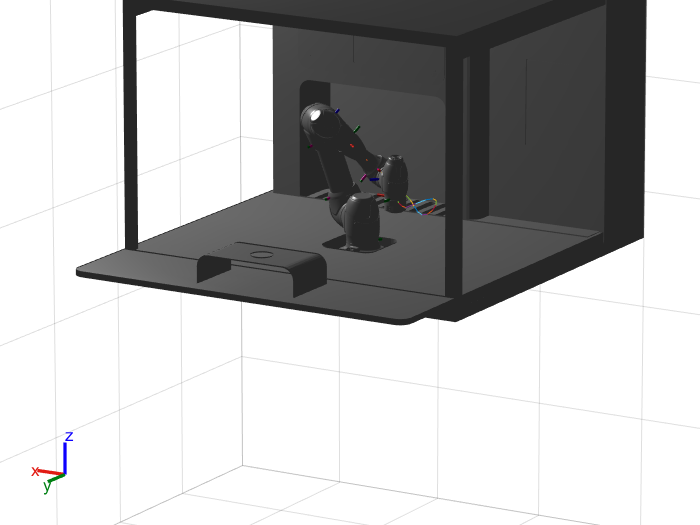

ans =      6     6


ans =      6    20


ans =      1    20


ans =      1    20


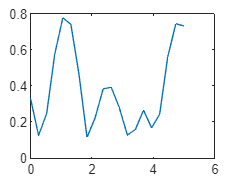

ans = 1×20 cell array
    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}    {6×6 double}


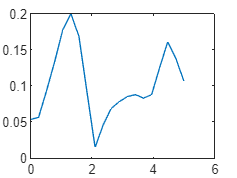

myrobot = importrobot('Doosan_Scatola_Girata.urdf');
q_traj_urdf = lemniscata_gerono_urdf(a,h,d_x,d_y,theta_x,theta_y, myrobot);